## Q1. Linear Programming

### a) Dual Problem

#### Minimise d such that:


$$d = 8y_{1} + 15y_{2}$$


#### Subject to: 


$$2y_1 + y_2 \geq 3
$$



$$2y_1 + 3y_2 \geq2
$$



$$y_1 + 3y_2 \geq1$$



$$y_1,y_2 \geq0$$


### b) Solving Problem P

objective $f= 3x +2y +1z$

so for linprog:


$$f = -(3, 2, 1)^T$$


subject to


$$A x \leq b$$


shown below:

f = -[3 2 1];

A = [2 2 1; 1 3 3];
b = [8; 15];

lb = zeros(length(f),1);

[x, fval] = linprog(f, A, b, [],[],lb,[])

Optimal solution found.



x =      4
     0
     0


fval = -12

% As this is a maximisation problem the true solution fval is *-1:
fval = -fval

fval = 12

### c) Solving the Dual Using Graphical Methods

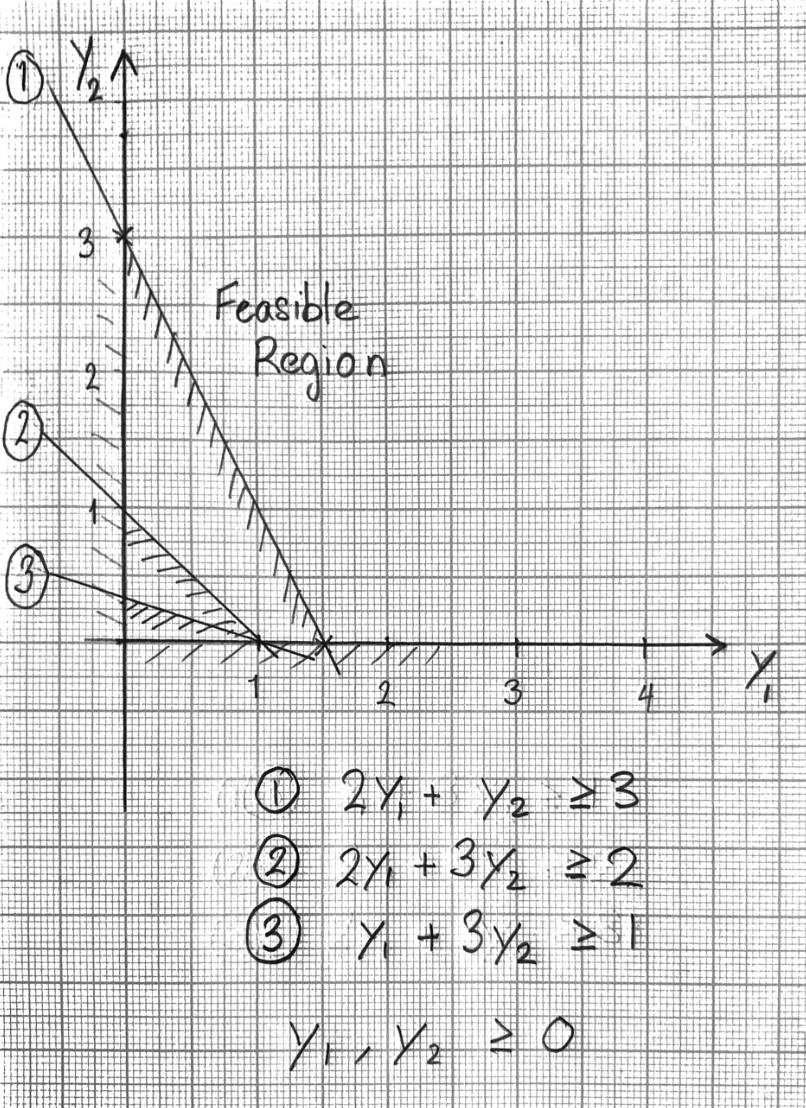 

***Figure 1: the constraints of the dual problem plotted. The constraints are numbered corresponding to the problem P variables that they are taken from.***

From the figure there are two feasible solutions (vertices) that may be suitable for the minimisation problem:

$Y_{sol1} = (0,3)$ or $Y_{sol2} = (1.5,0)
$

The optimal solution minimises $d = 8y_{1} + 15y_{2}$ and so it clear that $Y_{sol2} 
$ is optimal as it produces the smallest d value:

$Y^* = (1.5,0)$ with a value of 12.

#### This confirms that the optimal objective function values of problems P and D are equal and the strong duality theorem holds.

### d) Complementary Slackness Theorem

In the optimal solution of problem P, only the first variable is positive. The complementary slackness theorem states that the corresponding dual constraint (to the positive variable in P) is binding (not slack), whereas the constraints in D corresponding to the zero variables in the solution of P are slack. 

From the graph in figure 1 it is clear that constraints 2 and 3 are slack, as they do not effect the feasible region, this corresponds to variables $x_2 , x_3$ in the solution $X^*$ of P which are zero.

### e) Discussion of Solving the Primal vs Dual

#### The primal problem:

2 constrains ( 2 slack variables ) 

*n *variables 

#### The dual problem:

*n *constraints (*n *slack variables)

2 variables

- **Number of dimensions to be considered**

The dual problem will actually require more variables than just the main variables as the simplex style method that is used by linprog for solutions will use slack variables for all constraints to turn them into equality constraints with unknowns. From this aspect, the dual problem will likely become as more compex to solve as the total number of variables will remain the same, if the slack variables are included, and the number of constraints increases. 

- **Redundancy in constraints**

As shown previously, the complementary slackness theorem shows that for any zero variables in the optimal solution of the primal problem, the corresponding constraints in the dual are slack. This means that although the number of variables gets transposed to the number of constraints in the dual, many of them are likely to be redundant in the feasible region in the solution space.

- **Method of linprog solving**

Linprog uses a simplex style method for solving LP problems by default. However there is an option for linprog to use a different solver, this is accessed for large scale problems: linprog can use a linear interior point solver to get the optimal solution [1]. This method traverses the feasible region instead of checking the vertices and so is more resistant to the number of constraints:

the big O complexity of the interior point solver is given as:

$O{\left (n^{3.5}log {\left ( \frac{1}{\epsilon } \right )}\right )}$     [2]

Where n is the number of variables and $\epsilon$ is the target accuracy. In this description, the number of constraints does not impact the complexity and so it would be fair to conclude that the problem, P or D, with fewer true variables is the least complex from a computing standpoint. 

## References

**[1]** [http://www.ece.northwestern.edu/local-apps/matlabhelp/toolbox/optim/linprog.html](http://www.ece.northwestern.edu/local-apps/matlabhelp/toolbox/optim/linprog.html)

**[2] **[https://epubs.siam.org/doi/book/10.1137/1.9781611971453](https://epubs.siam.org/doi/book/10.1137/1.9781611971453) 